# EE6133 Multirate Digital Signal Processing

Experiment 2: Implementation of a DFT Filter Bank

Arjun Menon Vadakkeveedu, EE18B104

Electrical Engineering, IIT Madras

Nov 2021    

Link to the Git repository hosting the code, input and output files: [Github Link](https://github.com/arjunmenonv/DFT-Filter-Bank)

## Part 1: Input Reading and Type-2 Filter Design

[input, Fs_inp] = audioread('inp/music16khz.wav');
play = audioplayer(input, Fs_inp);
playblocking(play);

% LPF Filter Design parameters
fpass = (0.45/2)*Fs_inp;
fstop = (0.55/2)*Fs_inp;
fvector = [fpass fstop];
mag = [1 0];
dev = [0.01 0.01];
% Parks-McClellan Algorithm to estimate order of filter
[n, fo, mo, w ] = firpmord(fvector, mag, dev, Fs_inp)

n = 39

fo =          0
    0.4500
    0.5500
    1.0000


mo =      1
     1
     0
     0


w =      1
     1


### 1.1 firpm order estimation results

Ripple value        Order (n)       Type        Stopband Suppression (dB)

0.1                         14                  1                       -20dB

**0.01                       39                  2                       -40dB**

0.001                     65                  2                       -60dB   

The paramaters chosen for the analysis filter are highlighted in Bold.

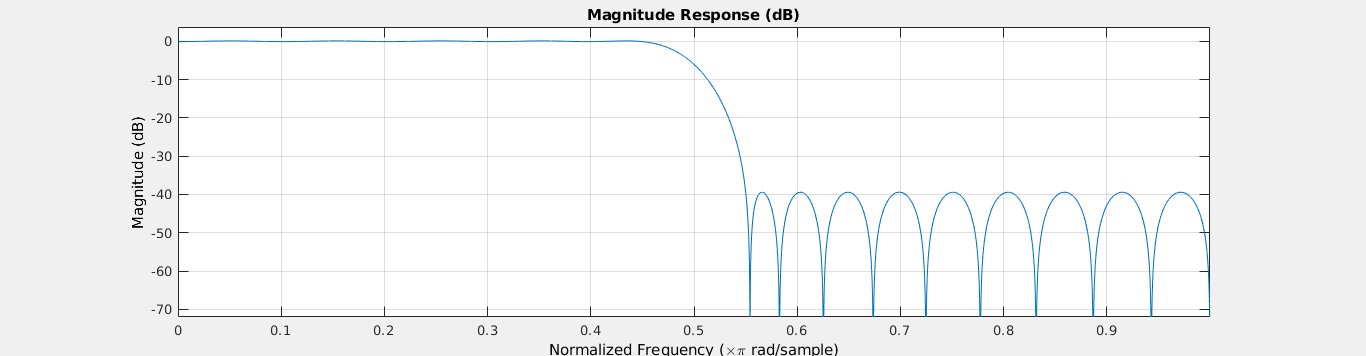

% if specs arent met for n, try n+1 or n+2
% since the filter is type 2 linear phase, n must be odd
analysisFilt = firpm(n, fo, mo, w );
% Mag spectrum of analysis prototype filter
fvtool(analysisFilt, 1);

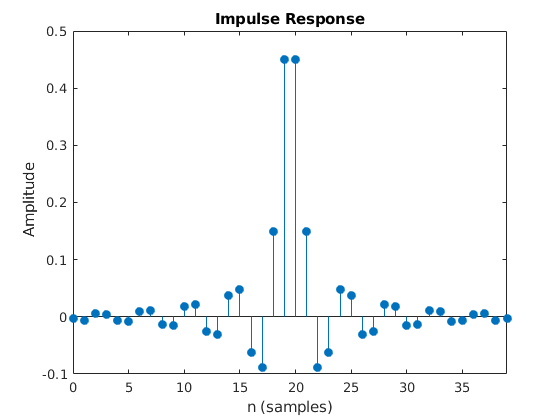

impz(analysisFilt);     % plot impulse resp

## Part 2: Input Processing using Analysis Filter and DFT Matrix

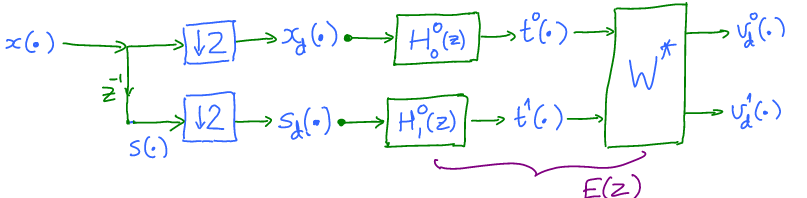

**Analysis Stage of the DFT-2 Filter-Bank**

% confirm that the impulse response is indeed linear phase 
diff = analysisFilt - analysisFilt(end:-1:1);
max(diff), min(diff)

ans = 0

ans = 0

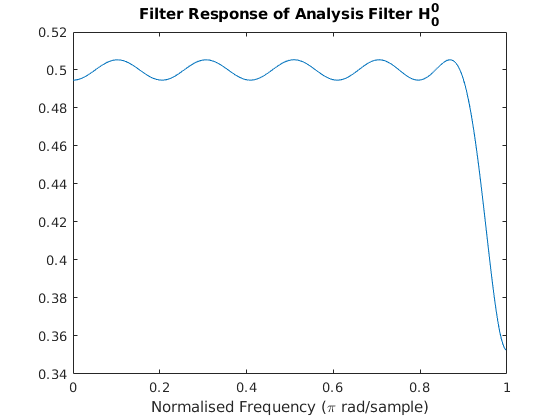

h0 = analysisFilt(1:2:end);
h1 = analysisFilt(2:2:end);
figure();
[H00, w] = freqz(h0);
plot(w/pi, abs(H00));
xlabel("Normalised Frequency (\pi rad/sample)")
title("Filter Response of Analysis Filter H_0^0");

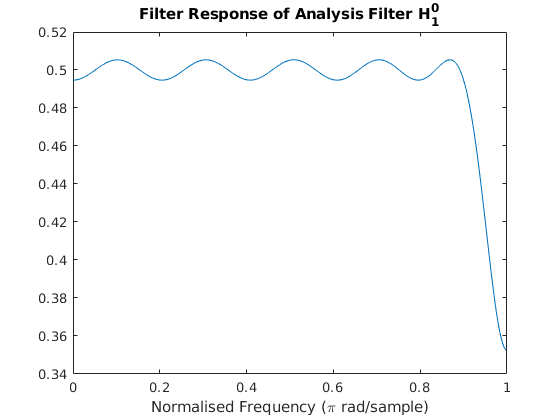

figure();
[H10, w] = freqz(h0);
plot(w/pi, abs(H10));
xlabel("Normalised Frequency (\pi rad/sample)")
title("Filter Response of Analysis Filter H_1^0");

W_ = [1, 1; 1, -1];  % 2x2 DFT matrix
x = input(2:end);
s = input(1:end);   % s(n) = x(n-1)
M = 2;  % downsampling factor 
xd = downsample(x, M);
sd = downsample(s, M);
t0 = filter(h0, 1, xd); t1 = filter(h1, 1, sd);
t = [t0, t1];
vd = t*W_;
%vd0 = vd(:, 1);
%vd1 = vd(:, 2);

## Part 3: Synthesis-side Filtering and Output Generation

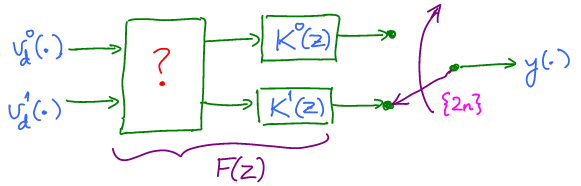

**Synthesis Stage of the DFT FB**

The block preceding the synthesis filters ($K^0(z)$ and $K^1(z)$) must be the 2 x 2 DFT Matrix. Let this matrix be denoted W.

W = M*inv(W_);   %W*W_ = M*I
ud = vd*W;
ud0 = ud(:, 1);
ud1 = ud(:, 2);

### 3.1 Synthesis Filter A

K0(z) = H1(z)

K1(z) = H0(z)

This choice will result in no-alias filtering, but does not provide Perfect Reconstruction


$$T(z) = \frac{1}{2}[H^0(z)H^1(-z) - H^1(z)H^0(-z)]
$$
 

        
$$= \frac{1}{2}[(H^0(z))^2 - (H^0(-z))^2]$$


Hence $T_{ZP}(\omega) $ is equal to:


$$T_{ZP}(\omega) = \frac{1}{2}[|H^0(e^{j\omega})|^2 + |H^1(e^{j\omega})|^2]$$


**Synthesis Commutator:**

Problem Statement specifies the following Synthesis Commutator ordering:


$$\quad
y[2n] = y_1[n] \\
y[2n+1] = y_0[n] $$


Thus, both $y_1(:) $ and $y_0(:)$ are upsampled by 2, and $y_0(:)$ is shifted right by 1 sample to get the output vector $y(:)$

k0 = h1;
k1 = h0;
y0 = filter(k0, 1, ud0);
y1 = filter(k1, 1, ud1);
y0up = [0; upsample(y0, M)];        % upsample by 2 and delay by 1 sample
y1up = [upsample(y1, M); 0];        % upsample by 2 
y = y0up + y1up;
out1 = y(1:end-1);
audiowrite("out/K1out.wav", out1, Fs_inp);

#### 3.1.1 Audio Playback and Comparison with Original Signal

As expected, there is no aliasing that is observed by the ear during playback of the output signal.

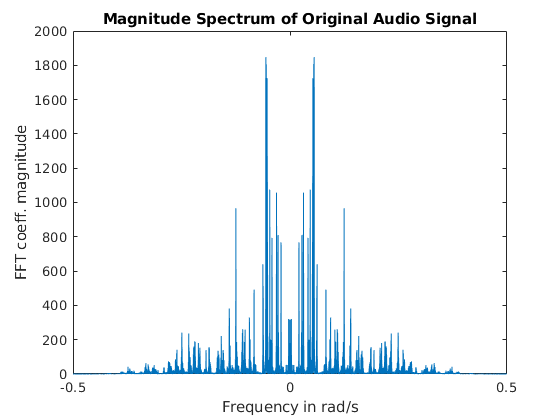

playOut1 = audioplayer(out1, Fs_inp);
playblocking(playOut1);
Naudio = 2^(ceil(log2(length(input))));
wAudio = linspace(-1/2, 1/2, Naudio);
fft_inp = fftshift(fft(input, Naudio));
fft_out1 = fftshift(fft(out1, Naudio));
figure();
plot(wAudio, abs(fft_inp));
xlabel("Frequency in rad/s");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Original Audio Signal");

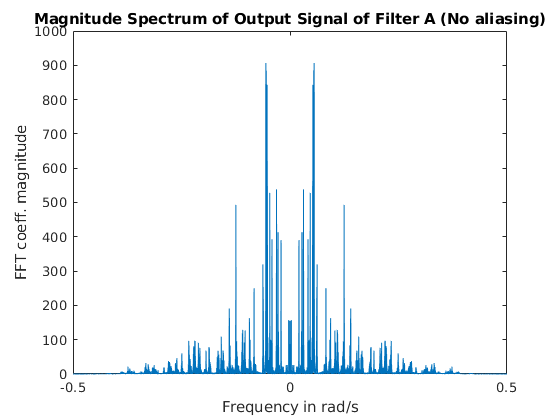

figure();
plot(wAudio, abs(fft_out1));
xlabel("Frequency in rad/s");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Output Signal of Filter A (No aliasing)");

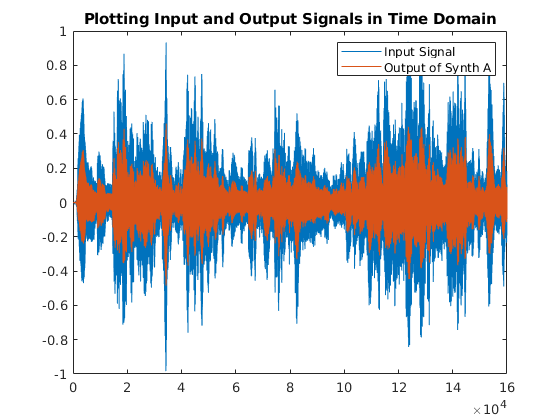

plot(input); hold on;
plot(out1);
title("Plotting Input and Output Signals in Time Domain");
legend(["Input Signal", "Output of Synth A"]);

The above plot indicates that the output signal captures most of the features of the input signal. The normalised versions of these signals are plotted in the following cell to remove the effect of scaling from the comparison.

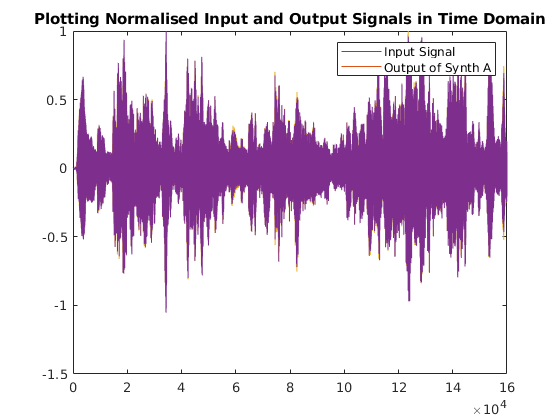

inp_norm = input/max(input);
out1_norm = out1/max(out1);
plot(inp_norm); hold on;
plot(out1_norm);
title("Plotting Normalised Input and Output Signals in Time Domain");
legend(["Input Signal", "Output of Synth A"]);
hold off;

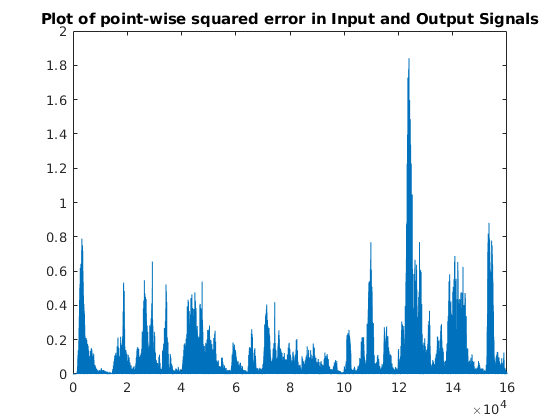

% Compute MSE in normalised signals:
figure();
sqrErr = (inp_norm - out1_norm).^2;
plot(sqrErr);
title("Plot of point-wise squared error in Input and Output Signals");

mse = mean(sqrErr)

mse = 0.0308

% mse of spectra:
fftOut1_norm = fft_out1/max(abs(fft_out1));
fftInp_norm = fft_inp/max(abs(fft_inp));
mseSpectra = mean((abs(fftOut1_norm - fftInp_norm)).^2)

mseSpectra = 0.0013

#### 3.1.2 T_{ZP}(\omega) for Synthesis Filter A

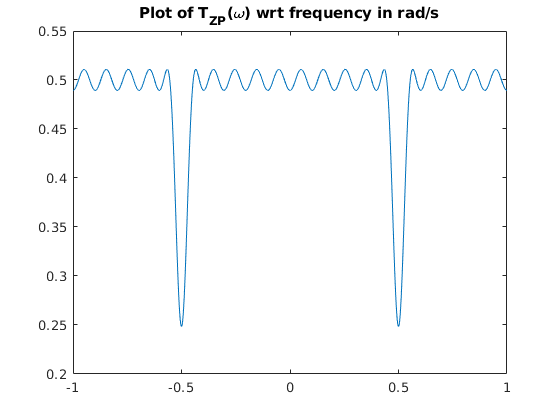

n=0:length(analysisFilt)-1;
N = 1000;
k = -N:N; w= (pi/N)*k; w1=(pi/N)*k-pi;
H0 = analysisFilt*exp(-j).^(n'*w);
H1 = analysisFilt*exp(-j).^(n'*w1);
figure();
T_zp=((abs(H0)).^2 + (abs(H1)).^2)/2;
plot(w/pi, T_zp);
title("Plot of T_{ZP}(\omega) wrt frequency in rad/s");

For Perfect Reconstruction, the spectrum of $T_{ZP}(\omega)$ must be flat. Hence Synthesis Filter Type A isn't PR.

### 3.2 Synthesis Filter B

K0(z) = H0(z)

K1(z) =H1(z)

k0 = h0;
k1 = h1;
y0 = filter(k0, 1, ud0);
y1 = filter(k1, 1, ud1);
y0up = [0; upsample(y0, M)];        % upsample by 2 and delay by 1 sample
y1up = [upsample(y1, M); 0];        % upsample by 2 
y = y0up + y1up;
out2 = y(1:end-1);
audiowrite("out/K2out.wav", out1, Fs_inp);

#### 3.2.1 Audio Playback and Comparison with Original Signal

The reduction in audio quality is apparent. The magnitude spectrum of the output signal corresponding to Synthesis Filter B shows clear aliasing with significant variation from the original spectrum at higher frequencies. This is an effect of aliasing.

playOut2 = audioplayer(out2, Fs_inp);
playblocking(playOut2);
Naudio = 2^(ceil(log2(length(input))));
wAudio = linspace(-1/2, 1/2, Naudio);
fft_inp = fftshift(fft(input, Naudio));
fft_out2 = fftshift(fft(out2, Naudio));
figure();
plot(wAudio, abs(fft_inp));
xlabel("Frequency in rad/s");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Original Audio Signal");

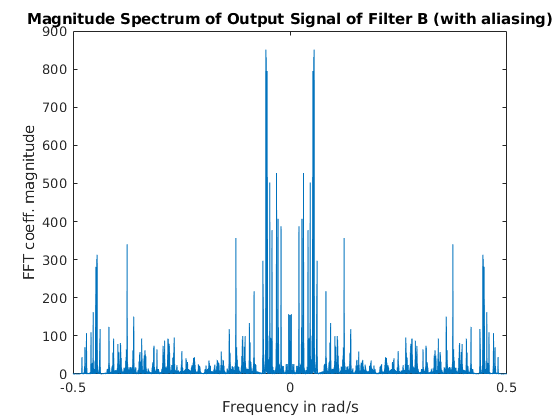

figure();
plot(wAudio, abs(fft_out2));
xlabel("Frequency in rad/s");
ylabel("FFT coeff. magnitude");
title("Magnitude Spectrum of Output Signal of Filter B (with aliasing)");